error_benign =     0.3282    0.5179    0.3249    0.3114    0.3793    0.2076    0.4139    0.2913


optrank_b = 2

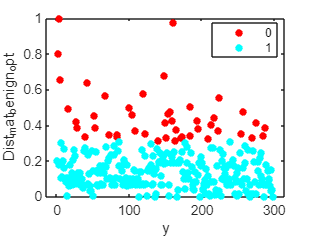

error_malignant =     2.2051    0.5664    0.2427    0.7378    0.5500    0.4441    0.5144    0.4845


optrank_m = 1

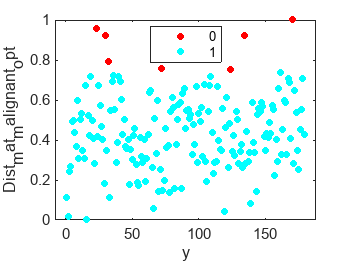

error_benign =     0.2908    0.2906    0.2205    0.3165    0.3485    0.2212    0.3523    0.4451


optrank_b = 8

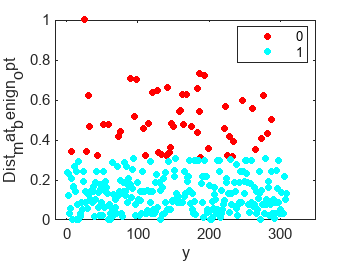

error_malignant =     0.5857    0.3742    2.1050    1.5387    0.4023    0.7982    0.6723    0.3340


optrank_m = 3

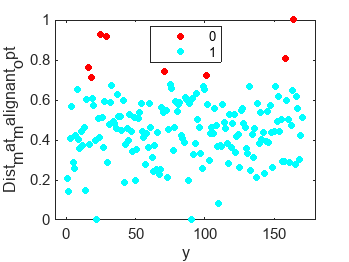

error_benign =     0.4206    0.5178    0.4592    0.4504    0.4690    0.3781    0.3591    0.4166


optrank_b = 2

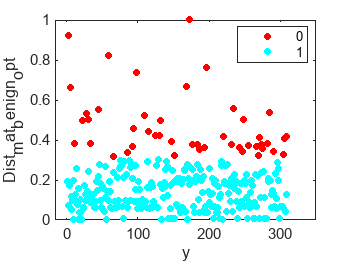

error_malignant =     0.8003    1.1571    0.4872    0.5470    0.4967    0.7247    0.8519    0.6907


optrank_m = 2

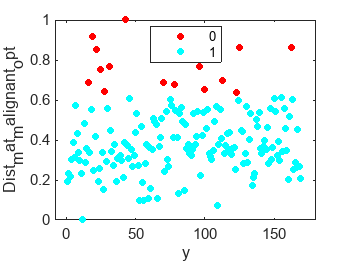

error_benign =     0.3220    0.3883    0.4544    0.4638    0.3040    0.3528    0.3045    0.3233


optrank_b = 4

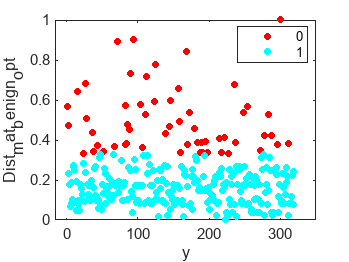

error_malignant =     0.6402    0.6958    1.6574    1.2361    1.2712    0.5994    0.4232    0.3866


optrank_m = 3

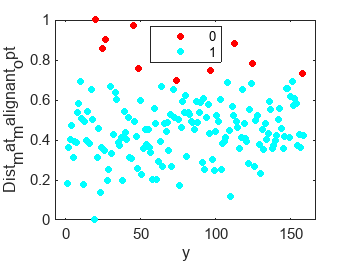

error_benign =     0.2791    0.4254    0.3442    0.4880    0.5465    0.5169    0.1809    0.3301


optrank_b = 5

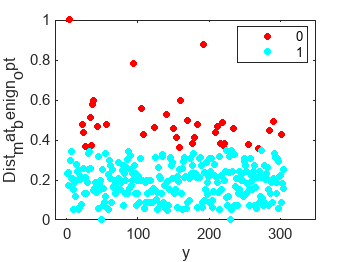

error_malignant =     1.7007    1.2590    0.9922    0.5381    0.6927    0.6948    0.3514    0.3458


optrank_m = 1

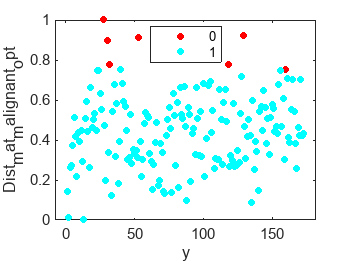

error_benign =     0.2244    0.3451    0.4311    0.7573    0.5049    0.3997    0.3611    0.5461


optrank_b = 4

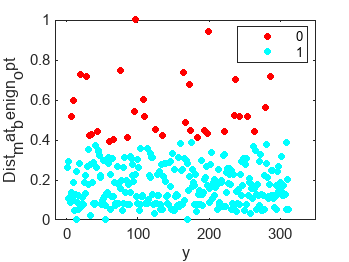

error_malignant =     0.6045    0.7176    0.4573    0.5679    0.7758    0.9511    2.3499    0.5140


optrank_m = 7

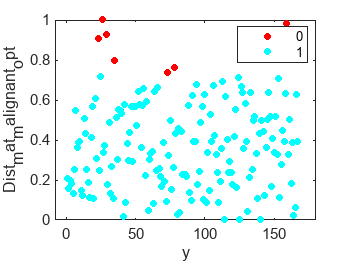

error_benign =     0.2554    0.2207    0.2665    0.3477    0.3009    0.4136    0.5444    0.6447


optrank_b = 8

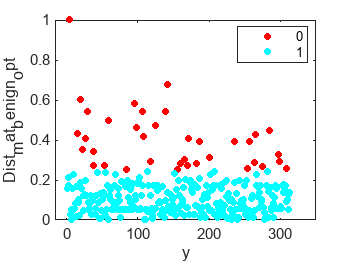

error_malignant =     0.5973    0.5428    0.4173    0.6544    0.3260    0.6761    0.8982    0.9583


optrank_m = 8

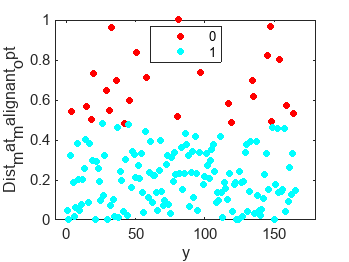

error_benign =     0.9354    1.2402    1.5641    1.0247    0.2900    0.3088    0.5060    0.6005


optrank_b = 3

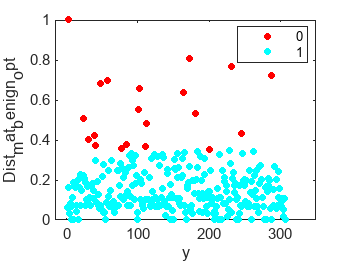

error_malignant =     2.8569    2.4939    0.4696    0.5490    0.6298    0.4478    0.9527    1.3965


optrank_m = 1

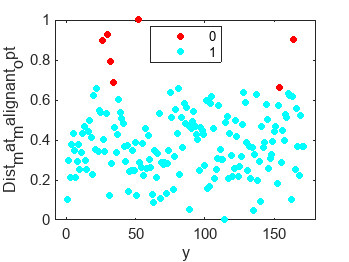

error_benign =     0.7921    0.8999    1.0823    0.8002    0.6589    2.9457    1.1809    0.4312


optrank_b = 6

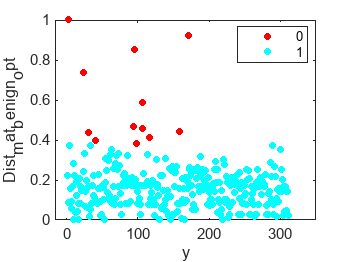

error_malignant =     3.1207    3.1011    0.6168    0.2219    0.9714    1.0975    0.3193    0.4421


optrank_m = 1

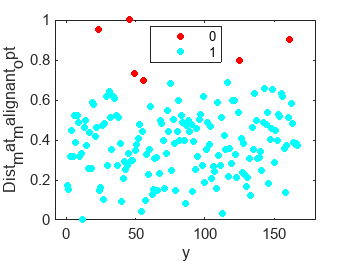

error_benign =     0.5188    0.4934    0.9079    0.6939    1.0147    0.6373    0.7319    0.2223


optrank_b = 5

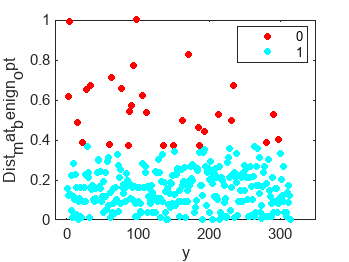

error_malignant =     2.1753    0.8859    0.1931    0.9296    0.7298    0.2610    0.4121    0.5455


optrank_m = 1

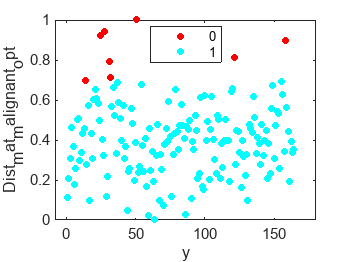

for j = [1,2,3,4,5,6,7,8,9,10]
    figure

    splitfolder=strcat('split',num2str(j));
    per =[20];%[50,40,30,20,10,5,2,0];
    for percent = per
        cd C:\Users\shukl\Documents\GitHub\CancerAceFiltering
        cd (splitfolder)

        folder=strcat('per',num2str(percent));
        cd (folder)
        my_file = strcat('cell_sample_noisy_per_',num2str(percent),'.csv');
        File=readmatrix(my_file,"NumHeaderLines",1);

        benign=File(File(:,10)==2,1:9);
        T_benign=benign.';
        malignant=File(File(:,10)==4,1:9);
        T_malignant=malignant.';

        folder_l1=strcat('ACE_dist_8optrank_angle_l1pca_per',num2str(percent));
        mkdir (folder_l1)

        ranks=[1,2,3,4,5,6,7,8];

        error_benign = nan(size(ranks));
        numbenign=length(T_benign);
        Dist_mat_benign_array=nan(length(ranks),numbenign);
        threshold_rank_b=nan(size(ranks));
        elbow_indx_rank_b=nan(size(ranks));

        for i = ranks
            %fprintf("Rank is %i \n", i) %i);
            cd C:\Users\shukl\Documents\GitHub\CancerAceFiltering\

            T_benign_temp=T_benign;
            Dist_mat_benign=[];


            BF_benign=l1pca_BF(T_benign,i,1,10,10,'');
            for k = 1 : numbenign
                A=T_benign(:,k);
                Dist_mat_benign(k)=norm((A-(BF_benign*BF_benign.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_benign,[],"all");
            max_val=max(Dist_mat_benign,[],"all");
            Dist_mat_benign= Dist_mat_benign-min_val;%]/[max_val-min_val]
            Dist_mat_benign=Dist_mat_benign /(max_val-min_val);


            Dist_mat_benign_array(i,:)=Dist_mat_benign;
            [Dist_mat_benign_asc,Indx_b]=sort(Dist_mat_benign,"ascend");


            [elbow_b_err_angle,elbow_indx_b]=knee_pt_angle((Dist_mat_benign_asc));

            error_benign(i)=elbow_b_err_angle;
            threshold_rank_b(i)=Dist_mat_benign_asc(elbow_indx_b);
            elbow_indx_rank_b(i)=elbow_indx_b;

% 
%             figure
%             plot((Dist_mat_benign_asc),'-s',"MarkerIndices",(elbow_indx_b),'MarkerFaceColor','red','MarkerSize',10 )
%             xlabel("index")
%             ylabel(["Distance Benign Asc for Rank",num2str(i)])
%             title(['Rank =',num2str(i) ])


        end

        
        error_benign

        [~,optrank_b]= max(error_benign)

        Dist_mat_benign_opt=Dist_mat_benign_array(optrank_b,:);
        threshold_dist_b= threshold_rank_b(optrank_b);
        elbow_indx_b_opt=elbow_indx_rank_b(optrank_b);

        ind_O_b=find(Dist_mat_benign_opt>threshold_dist_b);
        ind_I_b=find(Dist_mat_benign_opt<=threshold_dist_b);


        cluster_b=zeros(size(Dist_mat_benign_opt));
        cluster_b(ind_I_b)=1;
        figure
        y= 1:1:length(benign);
        numGroups = length(unique(cluster_b));
        gscatter(y,Dist_mat_benign_opt,cluster_b,hsv(numGroups))
% 
%         figure
%         plot(sort(Dist_mat_benign_opt,"ascend"),'-s',"MarkerIndices",(elbow_indx_b_opt),'MarkerFaceColor','red','MarkerSize',10 )
%         xlabel("index")
%         ylabel(["Distance Benign Asc for opt rank" ,num2str(optrank_b)])
%         title(['Rank opt for Benign =',num2str(optrank_b),"Split=",num2str(j)])
%         ind_O_b;


        T_benign_temp(:,ind_O_b)=[];
        length(T_benign_temp);

        Final_benign=T_benign_temp';
        Final_benign(:,10)=2;

    end
    %
    %
    %    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    nummalignant=length(T_malignant);
    error_malignant=nan(size(ranks));
    Dist_mat_mal_array=nan(length(ranks),nummalignant);
    threshold_rank_m=nan(size(ranks));
    elbow_rank_m=nan(size(ranks));


    for i=ranks
        %fprintf("Rank is %i \n", i) %i);

        T_malignant_temp=T_malignant;
        Dist_mat_malignant=[];

        BF_malignant=l1pca_BF(T_malignant,i,1,10,10,'');
        for k = 1 : nummalignant
            A=T_malignant(:,k);
            Dist_mat_malignant(k)=norm((A-(BF_malignant*BF_malignant.'*A)),1);
            k;
        end

        Dist_mat_malignant;
        min_val=min(Dist_mat_malignant,[],"all");
        max_val=max(Dist_mat_malignant,[],"all");
        Dist_mat_malignant= Dist_mat_malignant -min_val;%]/[max_val-min_val]
        Dist_mat_malignant=Dist_mat_malignant /(max_val-min_val);
        Dist_mat_mal_array(i,:)=Dist_mat_malignant;

        [Dist_mat_malignant_asc,Indx_m]=sort(Dist_mat_malignant,"ascend");


        [elbow_m_err_angle,elbow_indx_m]=knee_pt_angle((Dist_mat_malignant_asc));

        error_malignant(i)=elbow_m_err_angle;
        threshold_rank_m(i)=Dist_mat_malignant_asc(elbow_indx_m);
        elbow_rank_m(i)=elbow_indx_m;

%         figure
%         plot((Dist_mat_malignant_asc),'-*',"MarkerIndices",(elbow_indx_m),'MarkerFaceColor','red','MarkerSize',10 )
%         xlabel("Index")
%         ylabel("Distance Malignant Asc")
%         title(["Rank =", num2str(i)])


    end
    error_malignant
    [~,optrank_m]= max(error_malignant)

    Dist_mat_malignant_opt=Dist_mat_mal_array(optrank_m,:);
    threshold_dist_m= threshold_rank_m(optrank_m);
    elbow_indx_m_opt=elbow_rank_m(optrank_m);

    ind_O_m=find(Dist_mat_malignant_opt>threshold_dist_m);
    ind_I_m=find(Dist_mat_malignant_opt<=threshold_dist_m);

    cluster_m=zeros(size(Dist_mat_malignant_opt));
    cluster_m(ind_I_m)=1;

    figure
    y= 1:1:length(malignant);
    numGroups = length(unique(cluster_m));
    gscatter(y,Dist_mat_malignant_opt,cluster_m,hsv(numGroups))

%     figure
%     plot(sort(Dist_mat_malignant_opt,"ascend"),'-*',"MarkerIndices",(elbow_indx_m_opt),'MarkerFaceColor','red','MarkerSize',10 )
%     xlabel("Index")
%     ylabel("Distance Malignant Asc for opt rank")
%     title(["Opt Rank for Malignant=",num2str(optrank_m),"Split=",num2str(j)])

    ind_O_m;


    T_malignant_temp(:,ind_O_m)=[];
    length(T_malignant_temp);

    Final_malignant=T_malignant_temp';
    Final_malignant(:,10)=4;


    cd C:\Users\shukl\Documents\GitHub\CancerAceFiltering
    cd (splitfolder)
    cd (folder)

    cd (folder_l1)

    L1pca_file=(horzcat(Final_benign.',Final_malignant.')).';

    L1pca_file = array2table(L1pca_file);
    L1pca_file.Properties.VariableNames(1:10)=  {'Clump','UnifSize','UnifShape','MargAdh','SingEpiSize','BareNuc','BlandChrom','NormNucl','Mit','Class'};
    filel1pca=strcat('cell_sample_noisy_per',num2str(percent),'_ACE_l1pca.csv');
    writetable(L1pca_file,filel1pca);

end